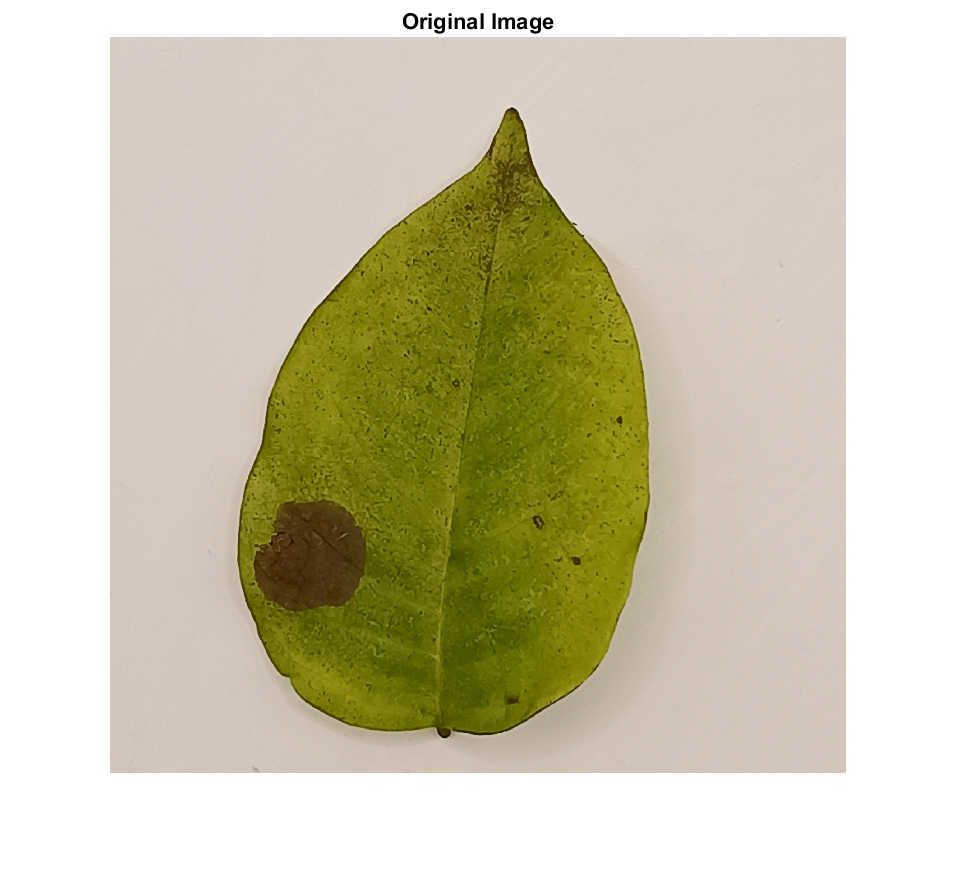

file = uigetfile('*.jpg;*.png');
img = imread(file);
% subplot(1,2,1);
imshow(img);title('Original Image');

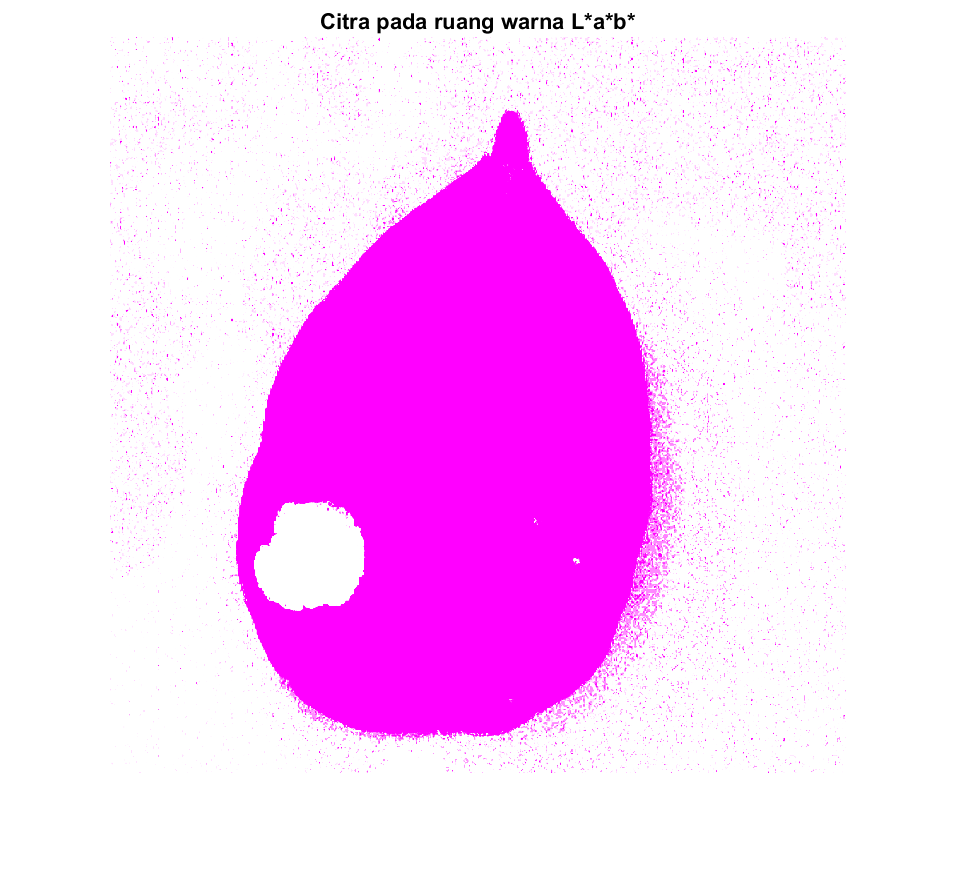


% change rgb to L*a*b
Lab = rgb2lab(img);
figure, 
imshow(Lab);title('Citra pada ruang warna L*a*b*');

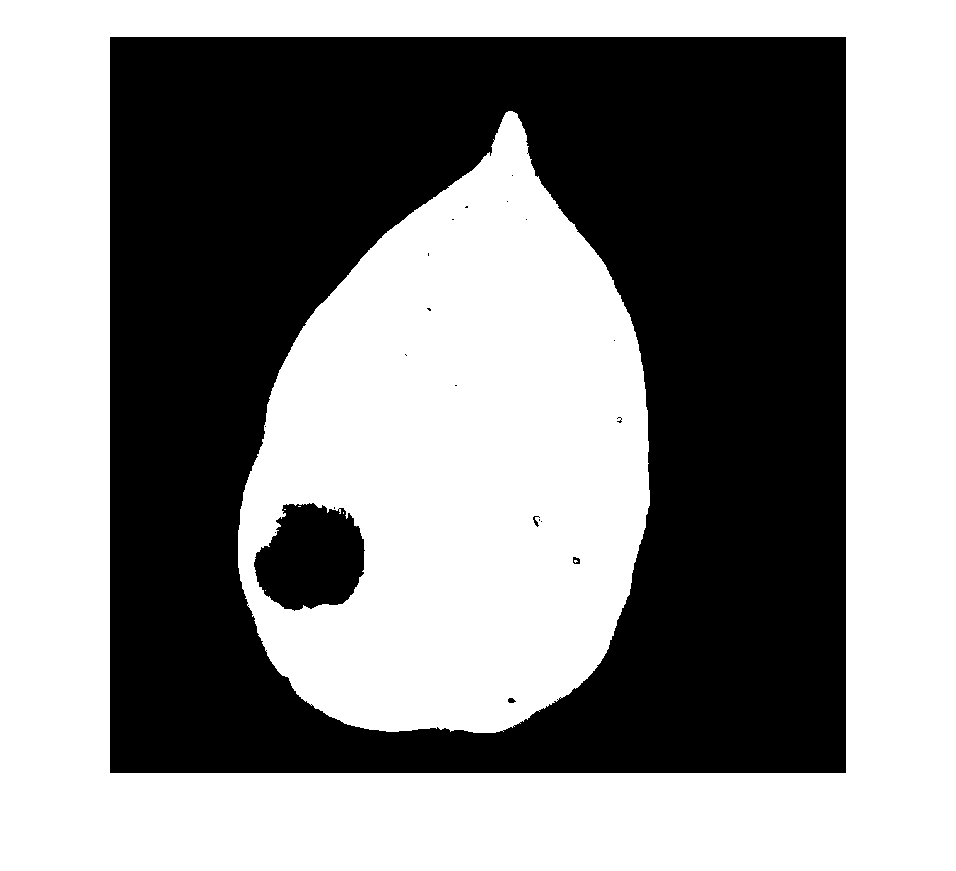


% extract component a and b from Lab
ab = double(Lab(:,:,2:3));
nrows = size(ab,1);
ncol = size(ab,2);
ab = reshape(ab,nrows*ncol,2);

% segmentation using k-means clustering
numberOfClass = 2;
indexes = kmeans(ab,numberOfClass);

ClassImage = reshape(indexes,nrows,ncol);
figure, 
imshow(ClassImage,[]);


% count area each cluster
area = zeros(numberOfClass,1);
    for n = 1:numberOfClass
        area(n)= sum(sum(ClassImage == n));
        
    end
    
% find the cluster with smallest area
[~,min_area] = min(area);
bw = ClassImage==min_area;
figure, 
imshow(bw);

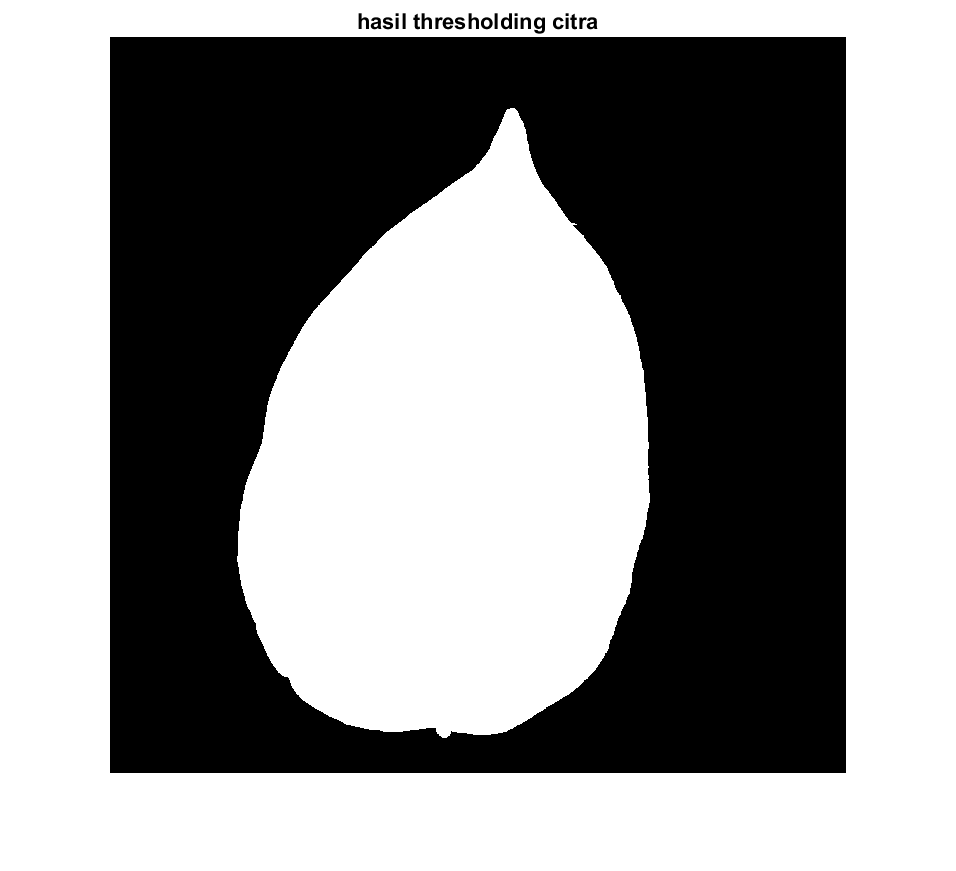


% ekstak komponen RGB
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% thresholding komponen blue
bw2 = ~imbinarize(B);
figure, 
imshow(bw2);title('hasil thresholding citra');

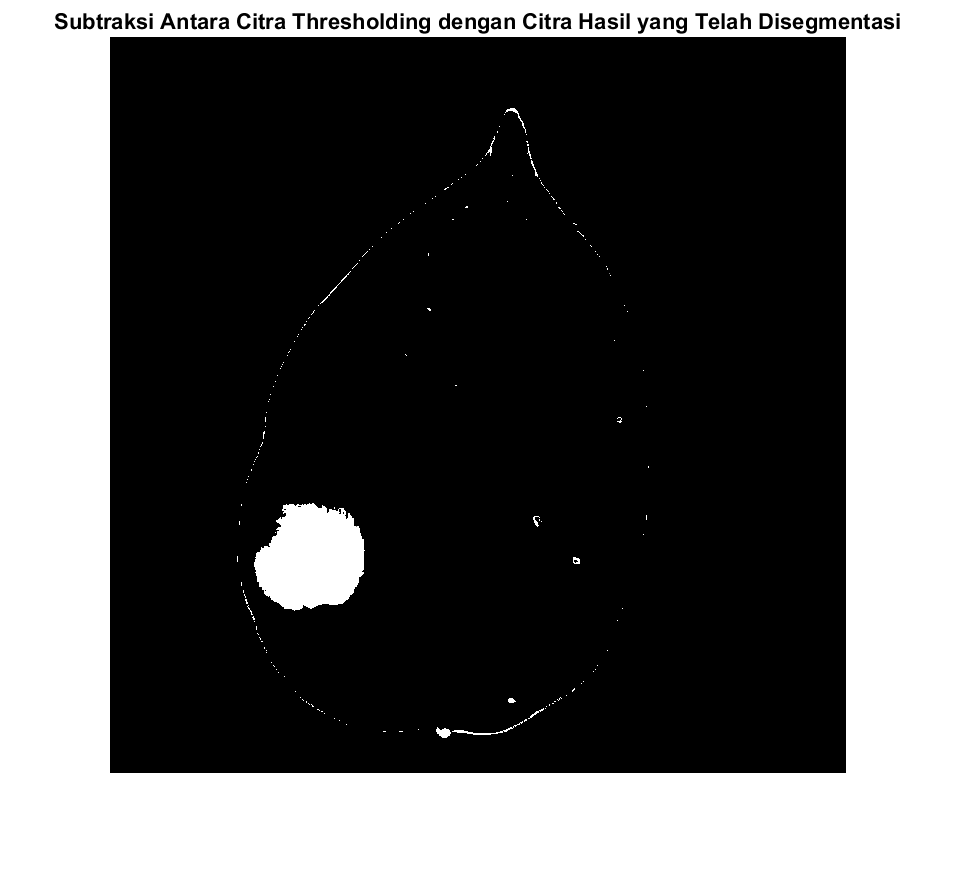


% subtraksi
bw3 = imsubtract(bw2,bw);
figure,
imshow(bw3);title('Subtraksi Antara Citra Thresholding dengan Citra Hasil yang Telah Disegmentasi');

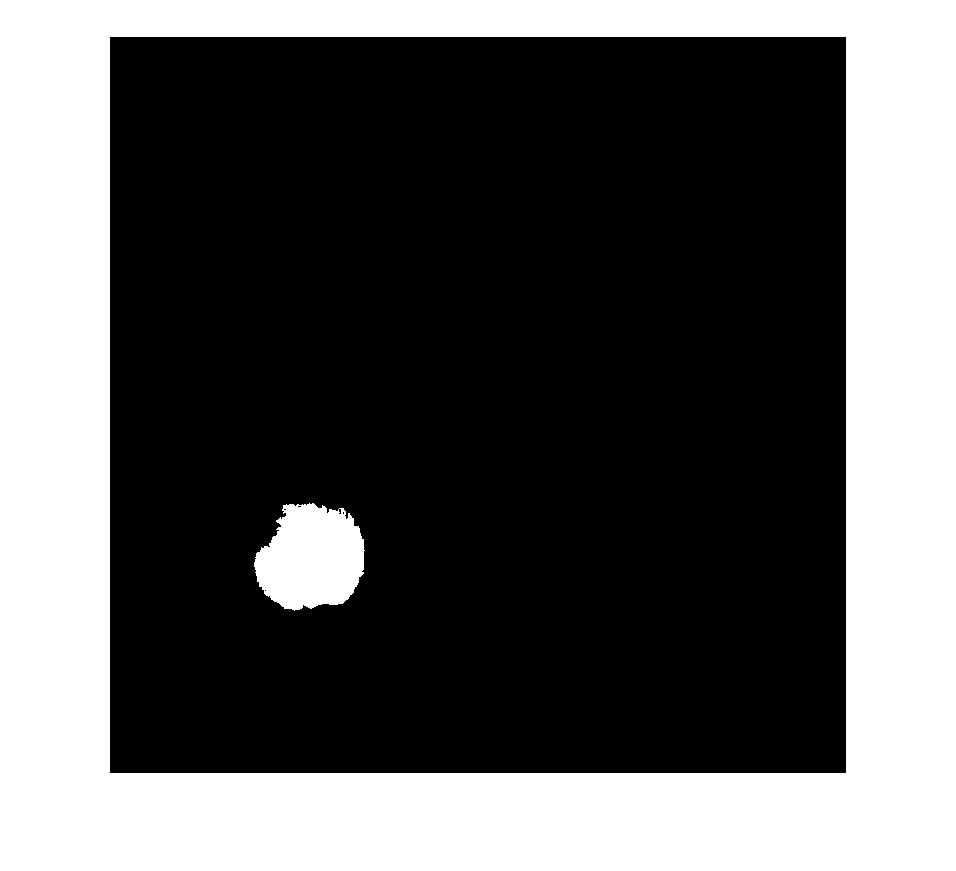


% menyempurnakan hasil segmentasi
bw4 = bwareaopen(bw3,6000);
figure, 
imshow(bw4);

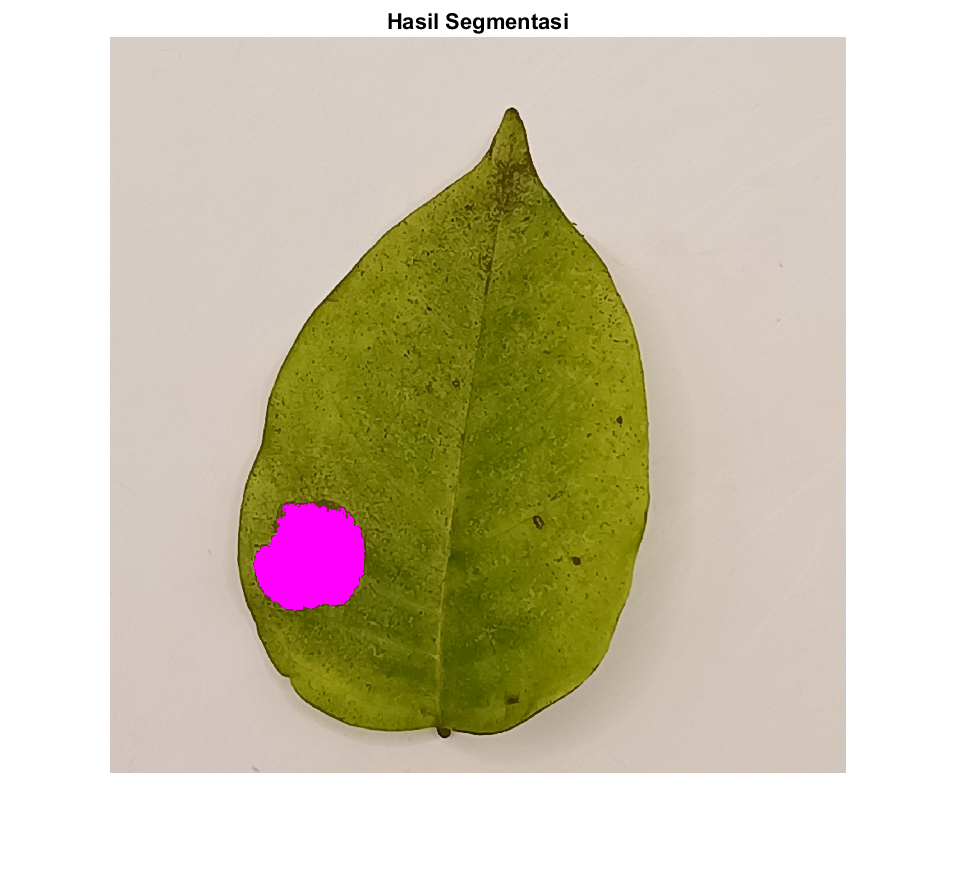


% menerapkan hasil segmentasi ke citra daun berpenyakit
R(bw4)= 255;
G(bw4)= 0;
B(bw4)= 255;

CitraHasil = cat(3,R,G,B);
% subplot(1,2,2);
figure,
imshow(CitraHasil);title('Hasil Segmentasi');